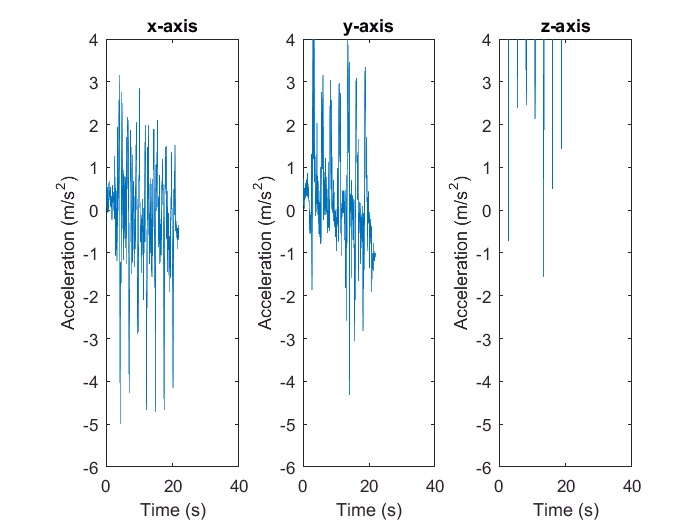

[accel_90, gyro_90] = parsePowerSenseData_1('square90bpm.csv');
makeAccelerometerPlots(accel_90,[],true);

ylim([0 10])

startcut = 300;
endcut = 800;
%%%% all x axis data 
x_accel = accel_90(:,2);
x_accel = x_accel(startcut:endcut);
fft_x = real(fft(x_accel));
[~, i] = max(fft_x)

i = 13

stem(fft_x)
Fs = 1/accel_90(2,1)-(accel_90(1,1));
%% cut off and moving average
x_accel = lr_accel(:,2);
x_accel = x_accel(startcut:endcut);
plot(x_accel)
fft_x = real(fft(x_accel));
[~, i] = max(fft_x)

i = 13

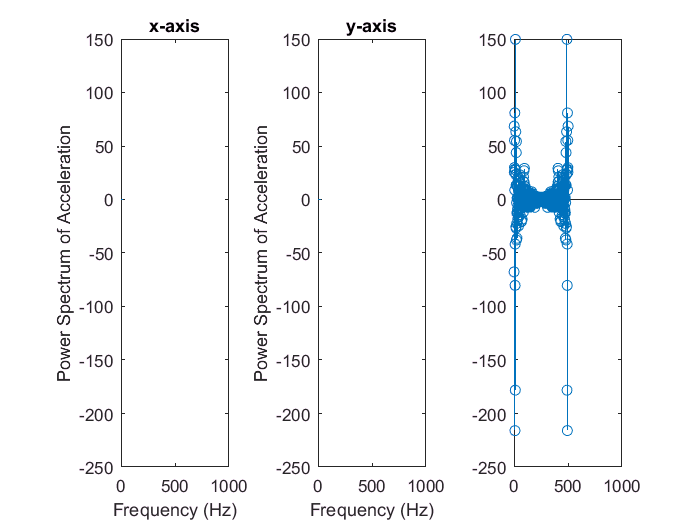

stem(fft_x)

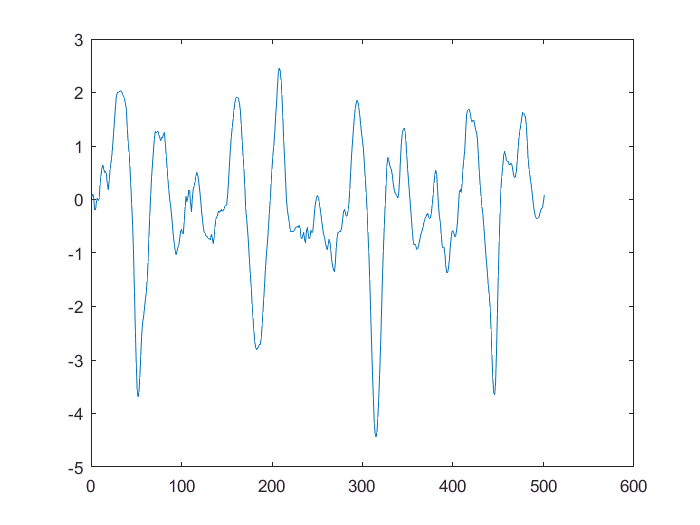

Fs = 1/lr_accel(2,1)-(lr_accel(1,1));
h = [1/6 1/6 1/6 1/6 1/6 1/6];          % moving average shape
x_accel2 = conv(x_accel, h);     % moving average convolution
x_accel2 = x_accel2(1:(end-length(h)+1));  % adjusting for conv
x_times = accel_90(:,1);        % grab times column
x_times = x_times(startcut:endcut);     % cutoff bad data
x_times = x_times-x_times(1);   % center unex times
figure


plot(x_accel2)  